## * CALISTA MAIN SCRIPT *

Example 1. iPSC differentiation into mesodermal and endodermal cells (`Example_1_BARGAJE_scRT_qPCR.m` script in the main folder of CALISTA)

Analysis of RT-qPCR data of Bargaje et al. ([Bargaje, et al, Cell population structure prior to bifurcation predicts efficiency of directed differentiation in human induced pluripotent cells. Proc. Natl. Acad. Sci. U. S. A. 114, 2271– 2276 (2017)](https://www.pnas.org/content/114/9/2271.long)).

We begin with changing the current directory in MATLAB to the CALISTA folder. Type '`cd`' in the command window then copy and paste the current path in '`curr_path`':

clc
clear all
close all

% Add path for CALISTA folder:
% mfilename=matlab.desktop.editor.getActiveFilename;
% curr_path=fileparts(which(mfilename));

% In windows
% curr_path='C:\Users\npgao\polybox\CALISTA-MATLAB_1.2.2';
% In MacOS
curr_path='/Users/nan/polybox/CALISTA-MATLAB_1.2.2';

cd(curr_path);
addpath(genpath(curr_path))
warning ('off','all');

## * 1-Data Import and Preprocessing *

Type '`help import_data`' in the command window for more information 

Run the following section and import Bargaje dataset (available in the subfolder *EXAMPLES/BARGAJE*).

%% *** 1-Data Import and Preprocessing ***
%
% Type 'help import_data' for more information 
%
% Specify pre-processing settings
INPUTS.data_type=1; % Single-cell RT-qPCR CT data
INPUTS.format_data=1; % Rows= cells and Columns= genes with time/stage info in the last column
%
% Specify single-cell clustering settings
INPUTS.optimize=1; % Find the optimal number of clusters
%
% Specify path analysis settings
INPUTS.plot_fig=1; % Plot figure of smoothened gene expression along path
INPUTS.hclustering=1; % Perform hierarchical clustering of gene expression for each path 
INPUTS.method=2; % Use pairwise correlation for the gene co-expression network (value_cutoff=0.8, pvalue_cutoff=0.01)
INPUTS.path_auto=0; % Manually define paths for further analysis

% Upload and pre-process data 
[DATA,INPUTS] = import_data(INPUTS);



**** Please upload normalized data. File formats accepted: .txt , .xlxs , .csv, .mat, .loom ****


Filtering genes by number of cells...

Filtering cells by number of genes...

% of zeros in the data  0.00

Selecting most variable genes...

Normalizing the data...

Finishing setup of the CALISTA data structure...

DONE.


## * 2-SINGLE-CELL CLUSTERING *

Type '`help CALISTA_clustering_main`' in the command window for more information. 

In this case, the number of clusters is determined using the eigengap plot. According to the eigengap plot below, we set the number of clusters to `5` in the command window:

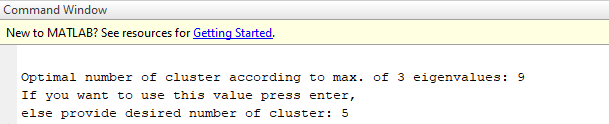


Detecting the optimal number of clusters with Eigengap heuristics...

CALISTA_clustering is running...
Progress:
..................................................
||||||||||||||||||||||||||||||||||||||||||||||||||

Constructing consensus matrix...
Elapsed time is 0.586881 seconds.


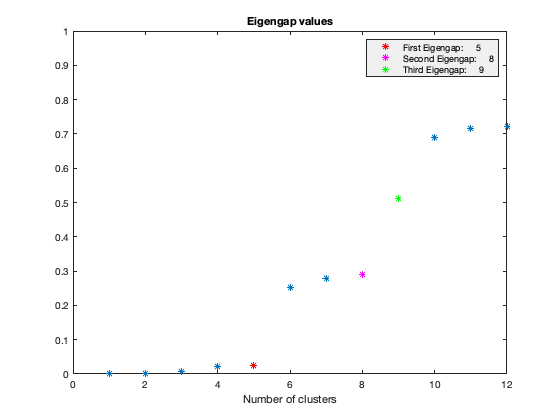


CALISTA_clustering is running...
Progress:
..................................................
||||||||||||||||||||||||||||||||||||||||||||||||||

Performing clustering based on consensus matrix...

Constructing consensus matrix...

Kmedois...
Elapsed time is 6.733242 seconds.

Plotting...


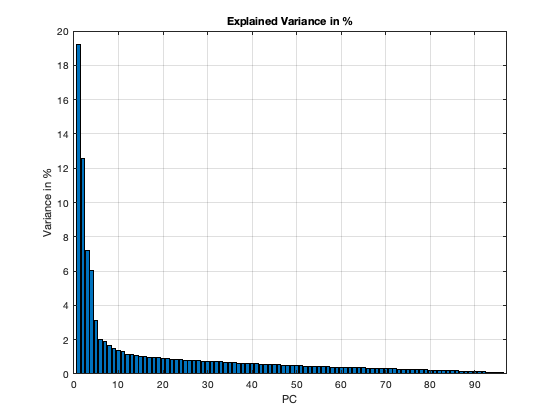

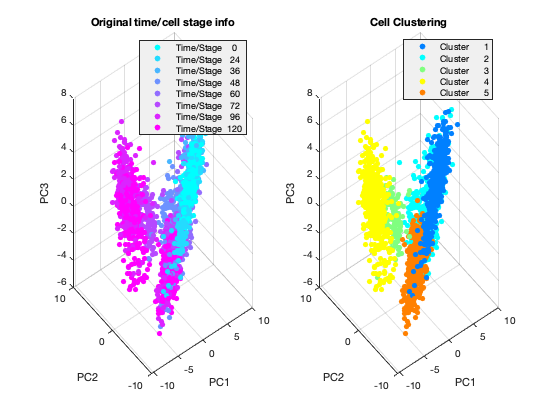

Elapsed time is 11.358781 seconds.

DONE.


[Results, DATA, INPUTS]=CALISTA_clustering_main(DATA,INPUTS);

If desired, users can remove cells from specific clusters from further analysis. In this example, we do not want to remove any clusters. Hence, we enter 0 (no cluster removal) and then 1 to proceed with lineage inference:

%  Cluster removal (if desired)
cluster_cut=input('Press 1 if you want to remove cell cluster(s). Press 0 otherwise: ');

if cluster_cut==1
    
   which_cut=input('Enter cluster index for removal (e.g 1 or [5 3]): ');
   cells_2_cut2=find(ismember(Results.final_groups,which_cut)==1);
   cells_2_cut2=DATA.cut_sort.abs_indices(cells_2_cut2);
   csvwrite('Cells_2_remove',cells_2_cut2)   
   RESULTS.cluster_cut = 1;
   fprintf('Cell''s indices to remove are saved in "Cells_2_remove.csv". Please run MAIN script again \n')
   return
end

Proceed=input(' Press 1 if you want to perform additional analysis (e.g. lineage inference, cell ordering) , 0 otherwise: ');
if ~Proceed
    return
end

## * 3-RECONSTRUCTION OF LINEAGE PROGRESSION *

Type '`help CALISTA_transition_main`' in the command window for more information. 

During the lineage inference step, CALISTA automatically generates and displays a lineage graph, obtained by adding an edge between two clusters in increasing cluster distances, until all clusters are connected to at least one other cluster. Subsequently, users can manually add or remove one edge at time based on the cluster distances.

**ATTENTION:** 

- to add an edge (press “p”), remove an edge (press “m”) or finalize the lineage progression graph (press “enter”), the MATLAB figure of the graph must appear in foreground without any modification (e.g., zooming, rotation). Note that the addition/removal of the edges are performed according to increasing/decreasing order of cluster distance.

- the final graph must be connected (i.e. there exists a path from any node/cluster to any other node/cluster in the graph), otherwise a warning will be returned.

Here, we do not need to remove any spurious edges, and hence we enter 0 upon queried:


CALISTA_transition is running...



4 edge(s) have been added and the graph is connected. 
If you want to add another edge press "p" 
If you want to remove an edge press "m" 
If you want to continue with the next step press "enter" 
(Please make sure that figure 101 is in the foreground and no additional tools are selected (e.g. zooming, rotation, data cursor etc.)) 

----------------------------------------------



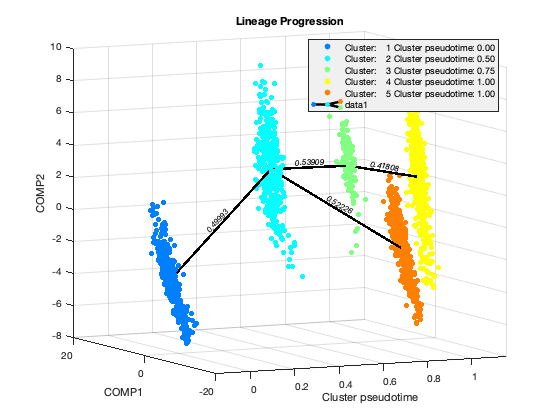

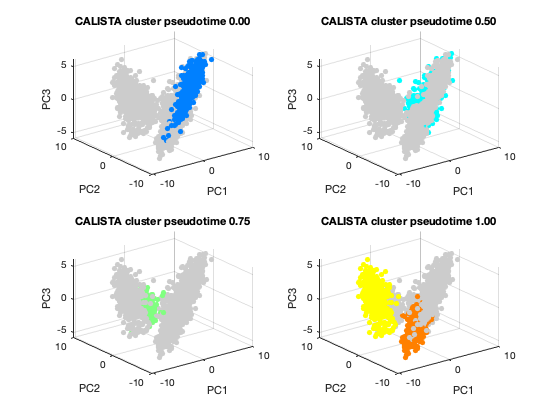

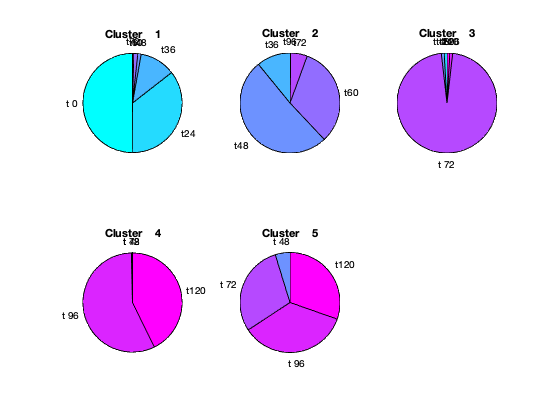


Plotting mean gene expressions...


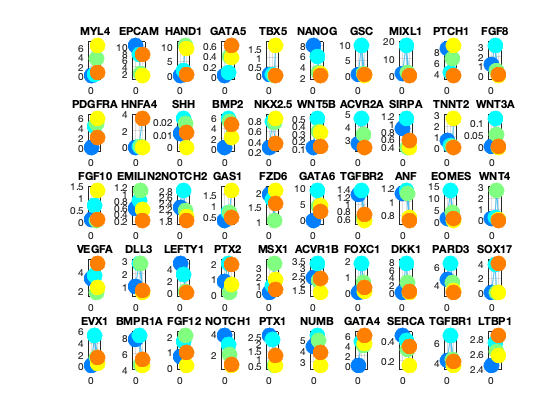


DONE.


[Results]=CALISTA_transition_main(DATA,INPUTS,Results);

% % Save 3D video
% figure(100)
% % daspect([2,2,0.3]);
% OptionZ.FrameRate=20;OptionZ.Duration=20.5;OptionZ.Periodic=true;
% CaptureFigVid([-20,10;-110,10;-190,80;-290,10;-380,10], 'CALISTA_lineage_3Dvideo',OptionZ)

## * 4-DETERMINATION OF TRANSITION GENES *

Type '`help CALISTA_transition_genes_main`' in the command window for more information. 

After reconstructing the lineage progression, we identify the key transition genes for any two connected clusters in the graph, based on the gene-wise likelihood difference between having the cells separately as two clusters and together as a single cluster. Larger differences in the gene-wise likelihood point to more informative genes. The transition genes are selected as those whose gene-wise likelihood differences make up to more than a certain percentage of the cumulative sum of the likelihood differences of all genes – set by` INPUTS.thr_transition_genes`.

[Results]=CALISTA_transition_genes_main(DATA,INPUTS,Results);


CALISTA_transition_genes is running...

DONE.


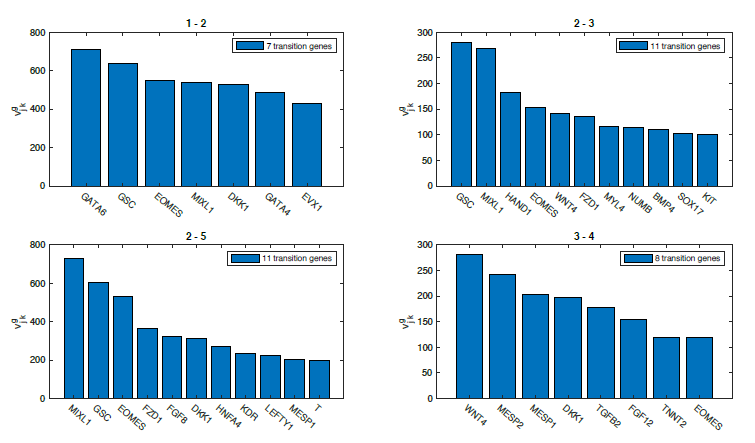

## * 5-PSEUDOTEMPORAL ORDERING OF CELLS *

Type '`help CALISTA_ordering_main`' in the command window for more information. 

For pseudotemporal ordering of cells, CALISTA performs maximum likelihood optimization for each cell using a linear interpolation of the cell likelihoods between any two connected clusters. The pseudotimes of the cells are computed by linear interpolation of the cluster pseudotimes, and correspond to the maximum point of the likelihood optimization above. Cells are subsequently assigned to the edges in the lineage progression graph. The following screenshot gives the results of this cell-to-edge assignment.


CALISTA_ordering is running...


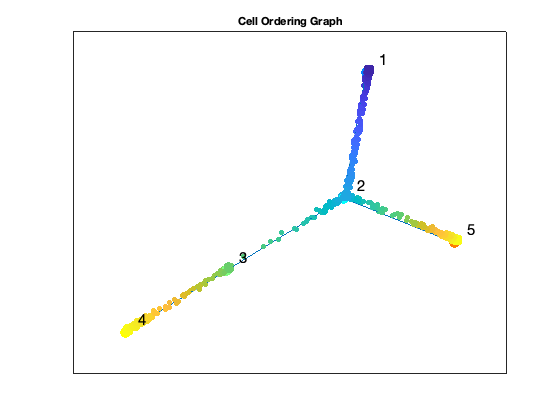


Waiting for plots...


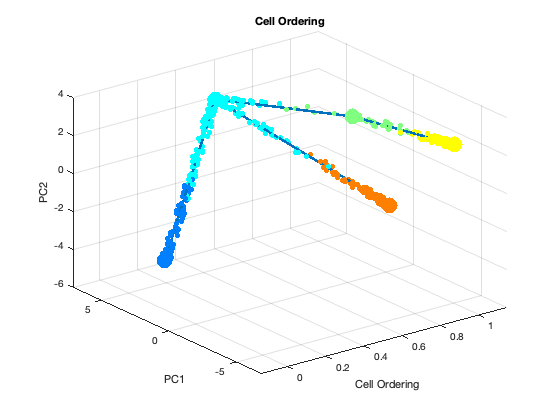


DONE.


[Results]=CALISTA_ordering_main_2(DATA,INPUTS,Results);

% [Results_transition_genes]=CALISTA_ordering_main_2_transition_genes(DATA,INPUTS,Results);

## * 6-LANDSCAPE PLOTTING *

Type '`help CALISTA_landscape_plotting_main`' in the command window for more information.

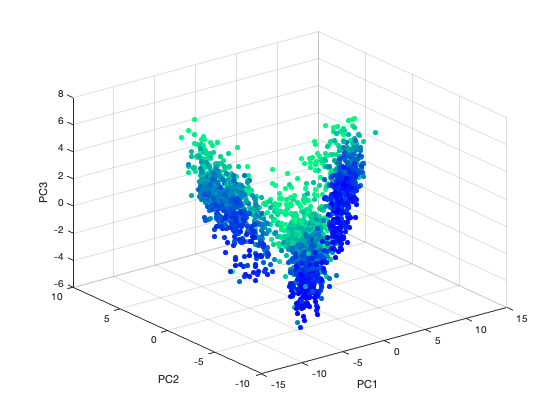

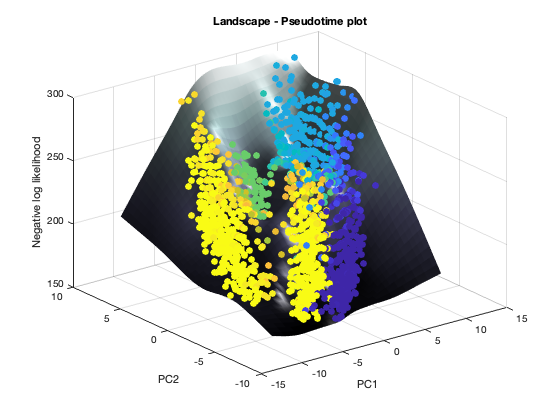

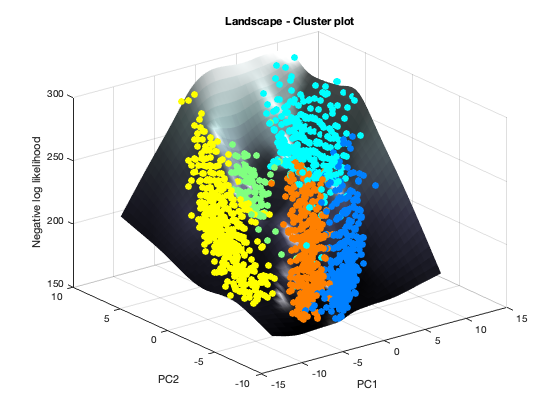

CALISTA_landscape_plotting_main(INPUTS,Results);

% CALISTA_landscape_plotting_main(INPUTS,Results_transition_genes);
% for k=1:Results_transition_genes.expected_clusters
%     Results_transition_genes.singleCELLclusterDATA{k}=Results_transition_genes.singleCELLclusterDATA{k}(:,Results_transition_genes.GENES.idx_tot_transition_genes);
%     
% end

## * 7-PATH ANALYSIS *

Type '`help CALISTA_path_main`' in the command window for more information. 

To perform path-specific analysis, users can enter 1 upon queried. In the following, we input two developmental paths of interest:` [1 2 3 4]` (mesodermal fate) and `[1 2 5]` (endodermal fate).

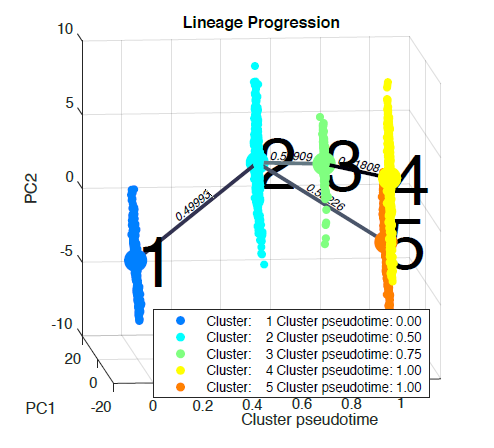

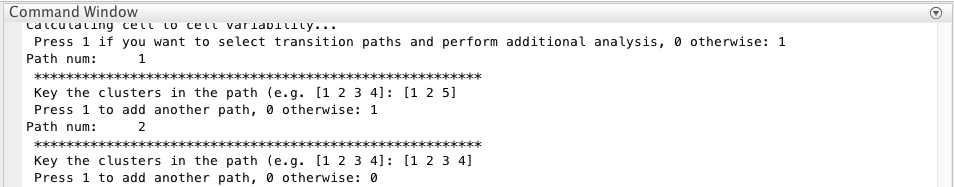

Proceed2=input(' Press 1 if you want to select transition paths and perform additional analysis, 0 otherwise: ');

if ~Proceed2
    return
end

Results=CALISTA_path_main(DATA,INPUTS,Results);


For each path, the post-analysis in CALISTA generates Clustergrams, moving-averaged gene expression profiles and co-expression networks for the transition genes detected previously based on cell orderings.